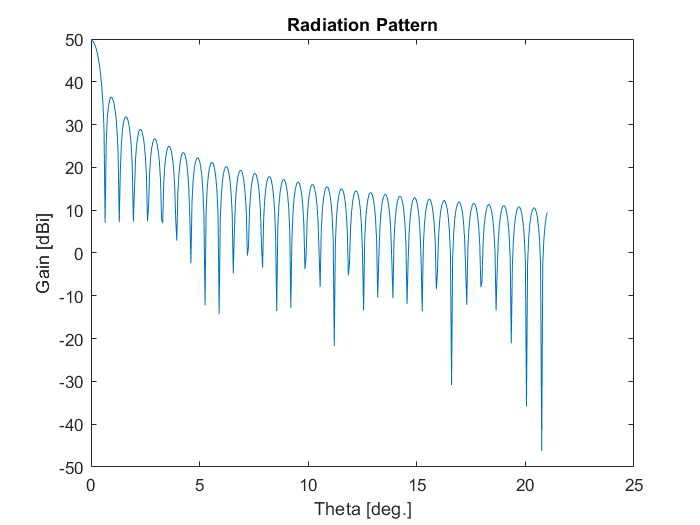

clc;
clear all;

%%% Radiation pattern
Data=importdata('RadiationPattern2.txt');
Theta_tx=Data.data(3601:4021,1);
Gain=Data.data(3601:4021,3);
figure()
plot(Theta_tx,Gain)
xlabel('Theta [deg.]')
ylabel('Gain [dBi]')
title('Radiation Pattern')



%Service Area
[Latitud,Longitud,AreaR] = read_data( );
    LatMin                   = -40/4;
    LatMax                   = 60/4;
    LonMin                   = 15;
    LonMax                   = 25;
[LatNA,LonNA,Ef_Area] = region( LatMin,LatMax,LonMin,LonMax,Latitud,Longitud,AreaR);
C1=size(LatNA(:,1));
C2=size(LonNA(1,:));
%%

% System 
Pt = 15; %20 %Pot Tx dBW
Rt=6378.2;      % Radius of the Earth in Km
rad=pi/180;     % Conversion from degrees to radians
Nivel = 3; %3 %Nivel Relat deseado

phi0 = 0; %45 %Elliptical beam inclination
las = 0; %0 %Lat subsatellite
los = 0; %1 %Lon subsatellite
hs = 35786; %35786 %Height Sat (km)

%%%Beam centers (lat,long)
nBeams=1;
 %laa1 = linspace(-30,30,nBeams);
 %laa1=[39.3 42 44.7 47.4 5.2 51 53.7 56.4 39.5 42.2] ;
 %loa1 =[-5.3 0 5.3 10.6 15.9 -0.5 6 12.3 11.4 16.7]; 
%  loa1=linspace(0,60,nBeams);
%  longitud = zeros(1,nBeams*nBeams);
%  latitud = zeros(1,nBeams*nBeams);
%  for i=1 : length(loa1)
%     longitud(1+(i-1)*length(laa1):(i)*length(laa1)) = loa1;
%     lattitud(1+(i-1)*length(loa1):(i)*length(loa1)) = laa1(i);
%  end
 laa1=5;
 loa1=20;
 
%laa1 =[39.3] ;
%loa1 =[-5.3]; 

Number_beams=size(laa1); %numbers of beams
thetamax=0.4.*ones(size(laa1)); %up to which the footprint is projected

%%%%EIRP preparation
EIRP=Pt+Gain;
EIRP_M=zeros(C1(1),C2(2));
latbeam=[];
lonbeam=[];
A1_p=LonNA;
A1_p(LonNA>180)=A1_p(LonNA>180)-360;
A1=A1_p(:)'; % change to a vector
B1=LatNA(:)';



%%%Footprint generator

for i=1:Number_beams(2) %%%for each beam
    j=1;
    while Theta_tx(j)<= thetamax(i)
       
        theta1=Theta_tx(j);
         theta2=Theta_tx(j);
         laa = laa1(1,i);
         loa = loa1(1,i);
        % The point in geographic coordinates is
        Ag=[Rt loa laa]';
        % I transform it to Cartesian coordinates
        [Ac]=LoLa2CT(Ag);
        % As the subsatellite point is not at (0,0) I rotate the Earth to put it there.
        [Aa]=CTrotCT(Ac,los,las)
        %  Now I transform it to Cartesian coordinates at the satellite.
        [As]=CT2CS(Aa,hs);
        % And finally I transform the Cartesians into angles of vision...
        [Sa]=CS2SV(As);       
 % We calculate the intersection of the line of sight with the Earth's surface.
        [Pt]=SV2CT(Sa,hs);
 % Now I undo the initial twist
        [Pt]=CTrotCTinv(Pt,los,las);
        % The distance from the satellite to the point of aiming Ra 
        [Psat]=LoLa2CT([Rt los las]')*(Rt+hs)/Rt;
        Xap=Sa(2)*cos(Sa(3)*rad);Yap=Sa(2)*sin(Sa(3)*rad);
        Ra=sqrt((Psat(1)-Pt(1)).^2+(Psat(2)-Pt(2)).^2+(Psat(3)-Pt(3)).^2);
        % Calculation of the contour diagram at dB level 
        Phi=[0:0.5:360];
        Xa=theta1.*cos((Phi)*rad);
        Ya=theta2.*sin((Phi)*rad);
        
        
        [Phi,Theta3] = cart2pol(Xa,Ya); % Phi is in radians
        
        Theta=Theta3.*sqrt(Nivel/3); %Beamwidth at dB level
        
        [Xa,Ya]=pol2cart(Phi,Theta);
        Za=ones(size(Xa));

        Pa=[Xa;Ya;Za];      % Points of the ellipse pointing to the subsatellite point
        Giro=[cos(-phi0*rad) sin(-phi0*rad) 0 ;-sin(-phi0*rad) cos(-phi0*rad) 0 ; 0 0 1];
        Ppa=Giro*Pa;        % Points of the rotated ellipse phi0
   
        % Now you have to point to the antenna pointing direction (Xap,Yap).
        Ppa(1,:)=Xap+Ppa(1,:); Ppa(2,:)=Yap+Ppa(2,:);
        
        
        % Conversion of Cartesian coordinates on the satellite to angles of view
        Theta1=sqrt(Ppa(1,:).^2+Ppa(2,:).^2);
        Phi1=atan2(Ppa(2,:),Ppa(1,:))/rad;
                
        Sv(2,:)=Theta1; Sv(3,:)=Phi1; Sv(1,:)=1;

        % We calculate the intersection of the lines of sight with the Earth's surface.

        [Pt]=SV2CT(Sv,hs);
        
        % Now I undo the initial twist
        [Pt]=CTrotCTinv(Pt,los,las); 
        
        %  Calculate distances to the satellite
        
        R=sqrt((Psat(1)-Pt(1,:)).^2+(Psat(2)-Pt(2,:)).^2+(Psat(3)-Pt(3,:)).^2);
        Dif=20*log10(Ra./R);
        %Convert Cartesian coordinates to geographic coordinates
        [Pg]=CT2LoLa(real(Pt));
        longitudes=Pg(2,:);
        latitudes=Pg(3,:);
        if(i>1)
       latbeam1=latbeam;
       lonbeam1=lonbeam; 
        else
             latbeam1=[];
       lonbeam1=[]; 
        end
       latbeam=[latbeam1 latitudes NaN];
       lonbeam=[lonbeam1 longitudes NaN];  
        
       
        S=size(latitudes);
        
        A=EIRP_M;%auxilar matriz EIRP
        

LonNA(LonNA>180)=LonNA(LonNA>180)-360;
             in = 1.*inpolygon(LonNA(:),LatNA(:),longitudes,latitudes);

            in_M=vec2mat(in,size(LatNA,1));
            in_M=in_M';
            A(in_M==1)=EIRP(ceil(j/2));
            EIRP_M(EIRP_M<A)=EIRP(ceil(j/2));

      

         j=j+1;

    end
end

Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


Aa = 	1.0e+03 *

    5.9707
    2.1732
    0.5559


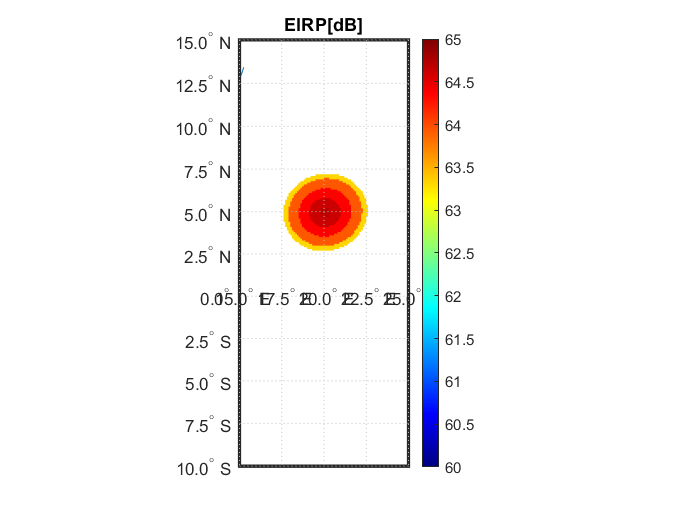



figure()
EIRP_M=real(EIRP_M);
EIRP_M(EIRP_M==0)=NaN;
cmin=60;
cmax=65;
map(LatMin,LatMax,LonMin,LonMax,LatNA,LonNA,EIRP_M,cmin,cmax);
title('EIRP[dB]');